# Simscape multibody model og Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Own REGBOT parameters

% RA = 2*5.5;    % ohm (2 motors)
% JA = 0.0008+0.00055; % motor inertia
% LA = 6.6e-3/2; % rotor inductor (2 motors)
% BA = 0.00000132+0.00000420;   % rotor friction
% Kemf = (0.00782+0.00819)/2; % motor constant
% Km = Kemf;
% % køretøj
% NG = 9.69; % gear
% WR = 0.03; % wheel radius
% Bw = 0.155; % wheel distance
% % model parts used in Simulink
% mmotor = 0.193;   % total mass of motor and gear [kg]
% mframe = 0.32;    % total mass of frame and base print [kg]
% mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
% mpdist =  0.10;   % distance to lit [m]
% % disturbance position (Z)
% pushDist = 0.1; % relative to motor axle [m]

## Controller design parameters

% Wheel velocity to voltage
N_i_vu = 2;
gamma_vu = 90;

% Tilt to velocity controller
N_i_tv = 10;
gamma_tv = 60;
alpha_tv = 0.00001;

% Pre velocity to tilt controller
N_i_vreft = 4;
gamma_vreft = 360+70;
alpha_vreft = 0.3;

% position to pre velocity controller
gamma_xvref = 360+80;
alpha_xvref = 0.3;

## Initial test parameters

x_test = 1;
x_size = 1;
v_size = 1;

## Sample controller values (initialisation)

K_vu = 15;     % Kp
t_i_vu = 0.05;   % Tau_i
Kffvu = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)
K_post = 1;
t_i_post = 1;
t_lead_tv = 0;
t_i_tv = 1;
K_tv = 1;
t_pre_tv = 0;
t_i_vreft = 1;
num_lead_vreft = 0;
den_lead_vreft = 1;
K_vreft = 1;
K_xvref = 1;
num_lead_xvref = 0;
den_lead_xvref = 1;
tau_pre_xvref = 0;

s = tf('s');

## Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gvu = minreal(tf(num, den))

Gvu =
 
                  7.023e05 s^3 + 7.023e08 s^2 - 5.083e07 s - 5.083e10
  -----------------------------------------------------------------------------------
  s^6 + 2418 s^5 + 1.317e06 s^4 + 1.872e08 s^3 + 2.371e09 s^2 - 3.032e10 s - 1.881e11
 
Continuous-time transfer function.
Model Properties


## Transfer function from previous exercise

Gvu = tf([1.1775 1.68],[1 7.334 7.141])

Gvu =
 
     1.177 s + 1.68
  ---------------------
  s^2 + 7.334 s + 7.141
 
Continuous-time transfer function.
Model Properties


pole(Gvu)

ans =    -6.1782
   -1.1558


zero(Gvu)

ans = -1.4268

## Bodeplot

pole(Gvu)

ans =    -6.1782
   -1.1558


isstable(Gvu)

ans = logical
   1


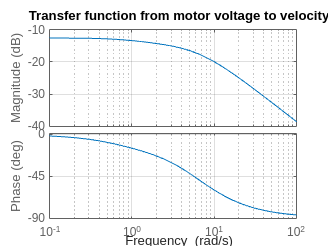

h = figure(100);
bode(Gvu)
grid on
title('Transfer function from motor voltage to velocity')

% saveas(h, 'motor to velocity.png');

## PI-Controller for voltage to velocity

% % Design parameters
% N_i = 4%N_i_vu;
% gamma_m = 100%gamma_vu;
% 
% phi_i = rad2deg(-atan(1/N_i));
% phi_G = -180+gamma_m-phi_i;
% 
% bode(Gvu)
% 
% [mag,phase,wout] = bode(Gvu);
% omega_c = interp1(squeeze(phase),wout,phi_G);
% tau_i = N_i/omega_c;
% C_i = tf([tau_i 1],[tau_i 0]);
% Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
% G_vu_ol = Kp*C_i*Gvu;
% G_vu_cl = G_vu_ol/(1+G_vu_ol);
% bode(G_vu_ol)
% step(G_vu_cl)

N_i = 3;
t_r = 0.2;

omega_c = 2.2/t_r;
tau_i = N_i/omega_c

tau_i = 0.2727

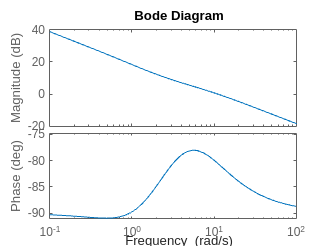

C_i = tf([tau_i 1],[tau_i 0]);
Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
G_vu_ol = Kp*C_i*Gvu;
G_vu_cl = G_vu_ol/(1+G_vu_ol);
bode(G_vu_ol)

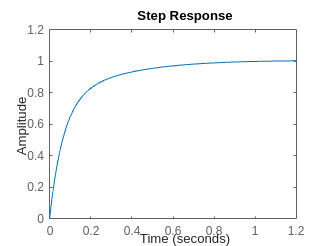

step(G_vu_cl)

## Flush values to model

K_vu = Kp

K_vu = 10.1357

t_i_vu = tau_i

t_i_vu = 0.2727

## **Transfer function from velocity to tilt using linearize**

% define points in model
ios(1) = linio(strcat(model,'/vel_cont'),1,'openinput');
ios(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gtv = minreal(tf(num, den))

Gtv =
 
                 -3.982e05 s^4 - 5.145e08 s^3 - 8.856e10 s^2 - 3.181e11 s - 9.517e08
  --------------------------------------------------------------------------------------------------
  s^7 + 2418 s^6 + 1.317e06 s^5 + 1.943e08 s^4 + 9.515e09 s^3 - 4.737e09 s^2 - 7.052e11 s - 1.889e12
 
Continuous-time transfer function.


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


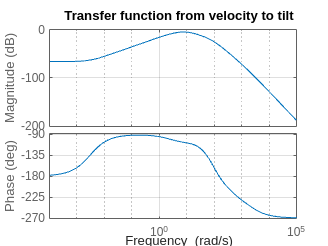

bode(-Gtv)
grid on
title('Transfer function from velocity to tilt')

[mag,phase,wout]=bode(Gtv);

## Post-Integrator

[gpeak,fpeak] = getPeakGain(-Gtv)

gpeak = 0.5823

fpeak = 7.5490

tau_i = 1/fpeak

tau_i = 0.1325

C_pi = -(tau_i*s+1)/(tau_i*s)

C_pi =
 
  -0.1325 s - 1
  -------------
    0.1325 s
 
Continuous-time transfer function.
Model Properties


G_post=Gtv*C_pi

G_post =
 
                5.274e04 s^5 + 6.855e07 s^4 + 1.225e10 s^3 + 1.307e11 s^2 + 3.182e11 s + 9.517e08
  -------------------------------------------------------------------------------------------------------------
  0.1325 s^8 + 320.4 s^7 + 1.744e05 s^6 + 2.574e07 s^5 + 1.26e09 s^4 - 6.275e08 s^3 - 9.342e10 s^2 - 2.502e11 s
 
Continuous-time transfer function.


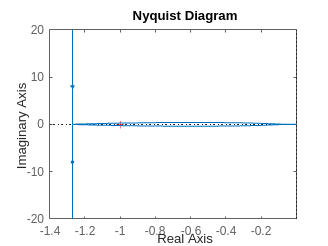

nyquist(G_post)

G_post_cl=minreal(G_post/(1+G_post))

G_post_cl =
 
                 3.982e05 s^5 + 5.175e08 s^4 + 9.244e10 s^3 + 9.866e11 s^2 + 2.402e12 s + 7.185e09
  ---------------------------------------------------------------------------------------------------------------
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.947e08 s^5 + 1.003e10 s^4 + 8.77e10 s^3 + 2.814e11 s^2 + 5.13e11 s + 7.185e09
 
Continuous-time transfer function.


isstable(G_post_cl)

ans = logical
   1


## Flush values to Simulink

K_post = -1

K_post = -1

t_i_post=tau_i

t_i_post = 0.1325

## Tilt to velocity controller PI-lead

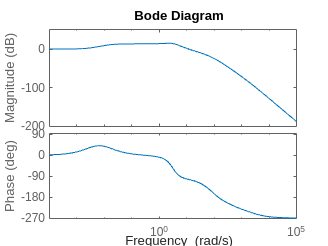

bode(G_post_cl)

% Design parameters
N_i =4%N_i_tv;

N_i = 4

gamma_m = 70%gamma_tv;

gamma_m = 70

alpha = 0.01%alpha_tv;

alpha = 0.0100



phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_post_cl);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.03235 s + 1
  -------------
    0.03235 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
   0.08088 s + 1
  ---------------
  0.0008088 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_post_cl),omega_c);
Kp = 1/mag;

G_tv_ol = minreal(Kp*C_i*C_D*G_post_cl)

G_tv_ol =
 
             9.866e07 s^7 + 1.325e11 s^6 + 2.849e13 s^5 + 1.285e15 s^4 + 1.993e16 s^3 + 1.192e17 s^2 + 2.276e17 s + 6.805e14
  -------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 3655 s^9 + 4.307e06 s^8 + 1.823e09 s^7 + 2.508e11 s^6 + 1.249e13 s^5 + 1.087e14 s^4 + 3.484e14 s^3 + 6.343e14 s^2 + 8.884e12 s
 
Continuous-time transfer function.


G_tv_cl = minreal(G_tv_ol/(1+G_tv_ol))

G_tv_cl =
 
                  9.866e07 s^7 + 1.325e11 s^6 + 2.849e13 s^5 + 1.285e15 s^4 + 1.993e16 s^3 + 1.192e17 s^2 + 2.276e17 s + 6.805e14
  ------------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 3655 s^9 + 4.307e06 s^8 + 1.921e09 s^7 + 3.833e11 s^6 + 4.099e13 s^5 + 1.394e15 s^4 + 2.028e16 s^3 + 1.198e17 s^2 + 2.276e17 s + 6.805e14
 
Continuous-time transfer function.



bode(G_tv_ol)
step(G_tv_cl)
bode(G_tv_cl)

[mag,phase,wout] = bode(G_tv_cl)

mag = mag(:,:,1) =

    1.0001


mag(:,:,2) =

    1.0002


mag(:,:,3) =

    1.0003


mag(:,:,4) =

    1.0005


mag(:,:,5) =

    1.0008


mag(:,:,6) =

    1.0014


mag(:,:,7) =

    1.0022


mag(:,:,8) =

    1.0036


mag(:,:,9) =

    1.0056


mag(:,:,10) =

    1.0086


mag(:,:,11) =

    1.0129


mag(:,:,12) =

    1.0188


mag(:,:,13) =

    1.0264


mag(:,:,14) =

    1.0359


mag(:,:,15) =

    1.0467


mag(:,:,16) =

    1.0579


mag(:,:,17) =

    1.0582


mag(:,:,18) =

    1.0677


mag(:,:,19) =

    1.0739


mag(:,:,20) =

    1.0740


mag(:,:,21) =

    1.0665


mag(:,:,22) =

    1.0512


mag(:,:,23) =

    1.0297


mag(:,:,24) =

    1.0046


mag(:,:,25) =

    0.9790


mag(:,:,26) =

    0.9555


mag(:,:,27) =

    0.9358


mag(:,:,28) =

    0.9209


mag(:,:,29) =

    0.9106


mag(:,:,30) =

    0.9044


mag(:,:,31) =

    0.9003


mag(:,:,32) =

    0.8950


mag(:,:,33) =

    0.8948


mag(:,:,34) =

    0.8816


mag(:,:,35) =

    0.8522


mag(:,:,36) =

    0.79

phase = phase(:,:,1) =

   -0.1486


phase(:,:,2) =

   -0.1677


phase(:,:,3) =

   -0.1905


phase(:,:,4) =

   -0.2148


phase(:,:,5) =

   -0.2406


phase(:,:,6) =

   -0.2678


phase(:,:,7) =

   -0.2976


phase(:,:,8) =

   -0.3328


phase(:,:,9) =

   -0.3795


phase(:,:,10) =

   -0.4495


phase(:,:,11) =

   -0.5627


phase(:,:,12) =

   -0.7500


phase(:,:,13) =

   -1.0559


phase(:,:,14) =

   -1.5391


phase(:,:,15) =

   -2.2690


phase(:,:,16) =

   -3.3150


phase(:,:,17) =

   -3.3539


phase(:,:,18) =

   -4.7283


phase(:,:,19) =

   -6.5184


phase(:,:,20) =

   -8.6355


phase(:,:,21) =

  -10.9699


phase(:,:,22) =

  -13.3784


phase(:,:,23) =

  -15.7295


phase(:,:,24) =

  -17.9473


phase(:,:,25) =

  -20.0356


phase(:,:,26) =

  -22.0770


phase(:,:,27) =

  -24.2169


phase(:,:,28) =

  -26.6449


phase(:,:,29) =

  -29.5840


phase(:,:,30) =

  -33.2882


phase(:,:,31) =

  -38.0450


phase(:,:,32) =

  -43.9780


phase(:,:,33) =

  -44.1663


phase(:,:,3

wout = 1.0e+05 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


[gpeak,fpeak] = findpeaks(squeeze(mag))

gpeak = 1.0740

fpeak = 20

tau_pre = 1/wout(fpeak(end))

tau_pre = 0.0633

G_pre = 1/(s*tau_pre+1)

G_pre =
 
        1
  -------------
  0.06329 s + 1
 
Continuous-time transfer function.
Model Properties


G_tv_pre = G_tv_cl*G_pre

G_tv_pre =
 
                               9.866e07 s^7 + 1.325e11 s^6 + 2.849e13 s^5 + 1.285e15 s^4 + 1.993e16 s^3 + 1.192e17 s^2 + 2.276e17 s + 6.805e14
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  0.06329 s^11 + 232.3 s^10 + 2.762e05 s^9 + 1.259e08 s^8 + 2.618e10 s^7 + 2.977e12 s^6 + 1.292e14 s^5 + 2.677e15 s^4 + 2.786e16 s^3 + 1.342e17 s^2 + 2.276e17 s + 6.805e14
 
Continuous-time transfer function.


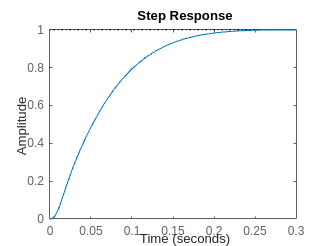

step(G_tv_pre)

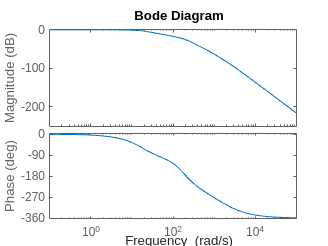

bode(G_tv_pre)

## Flush values to simulink

t_i_post

t_i_post = 0.1325

t_lead_tv = tau_D

t_lead_tv = 0.0809

t_i_tv = tau_i

t_i_tv = 0.0324

K_tv = Kp

K_tv = 2.4780

t_pre_tv = tau_pre

t_pre_tv = 0.0633

## Transfer function from reference tilt to velocity using linearize

% define points in model
ios(1) = linio(strcat(model,'/tilt_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_vreft = minreal(tf(num, den))

G_vreft =
 
                         -2.787e08 s^6 - 2.905e11 s^5 - 1.183e13 s^4 - 8.356e13 s^3 + 6.189e14 s^2 + 7.569e15 s + 1.726e16
  -----------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2434 s^9 + 1.435e06 s^8 + 3.164e08 s^7 + 3.007e10 s^6 + 1.41e12 s^5 + 3.187e13 s^4 + 3.481e14 s^3 + 1.707e15 s^2 + 2.909e15 s + 8.696e12
 
Continuous-time transfer function.


## Reference tilt to velocity controller

isstable(G_vreft)

ans = logical
   1


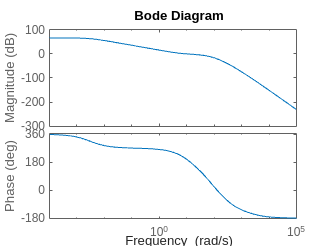

bode(G_vreft)



% Design parameters
N_i = 5%N_i_vreft;

N_i = 5

gamma_m = 70+360%gamma_vreft;

gamma_m = 430

alpha = 0.7 %alpha_vreft;

alpha = 0.7000



phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_vreft);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  2.214 s + 1
  -----------
    2.214 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.5292 s + 1
  ------------
  0.3704 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_vreft),omega_c);
Kp = 1/mag;

G_vreft_ol = minreal(Kp*C_i*C_D*G_vreft)

G_vreft_ol =
 
                     -1.195e08 s^8 - 1.248e11 s^7 - 5.361e12 s^6 - 4.779e13 s^5 + 1.771e14 s^4 + 3.835e15 s^3 + 1.522e16 s^2 + 2.009e16 s + 6.315e15
  ---------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2437 s^11 + 1.441e06 s^10 + 3.203e08 s^9 + 3.092e10 s^8 + 1.491e12 s^7 + 3.568e13 s^6 + 4.341e14 s^5 + 2.647e15 s^4 + 7.518e15 s^3 + 7.861e15 s^2 + 2.347e13 s
 
Continuous-time transfer function.


G_vreft_cl = minreal(G_vreft_ol/(1+G_vreft_ol))

G_vreft_cl =
 
                          -1.195e08 s^8 - 1.248e11 s^7 - 5.361e12 s^6 - 4.779e13 s^5 + 1.771e14 s^4 + 3.835e15 s^3 + 1.522e16 s^2 + 2.009e16 s + 6.315e15
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2437 s^11 + 1.441e06 s^10 + 3.203e08 s^9 + 3.08e10 s^8 + 1.367e12 s^7 + 3.032e13 s^6 + 3.864e14 s^5 + 2.824e15 s^4 + 1.135e16 s^3 + 2.308e16 s^2 + 2.012e16 s + 6.315e15
 
Continuous-time transfer function.


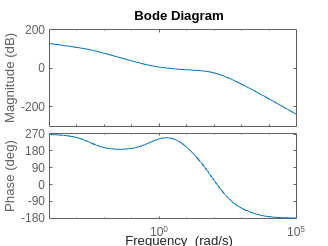


bode(G_vreft_ol)

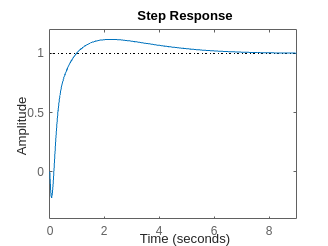

step(G_vreft_cl)

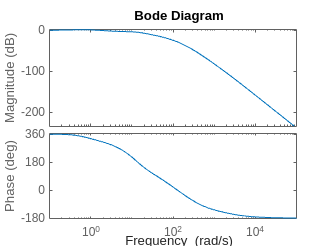

bode(G_vreft_cl)

## Flush values to simulink

t_i_vreft = tau_i

t_i_vreft = 2.2138

[num_lead_vreft,den_lead_vreft] = tfdata(C_D,'v')

num_lead_vreft =     0.5292    1.0000


den_lead_vreft =     0.3704    1.0000


K_vreft = Kp

K_vreft = 0.3001

## Transfer function from vel_pre to x

% define points in model
ios(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/x_pos'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_xvref = minreal(tf(num, den))

G_xvref =
 
                     -4.182e05 s^9 - 5.215e08 s^8 - 1.075e11 s^7 - 4.192e12 s^6 - 4.282e13 s^5 + 5.647e13 s^4 + 3.121e15 s^3 + 1.764e16 s^2 + 3.917e16 s + 3.095e16
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^13 + 2437 s^12 + 1.441e06 s^11 + 3.274e08 s^10 + 3.808e10 s^9 + 1.525e12 s^8 + 3.036e13 s^7 + 3.666e14 s^6 + 2.687e15 s^5 + 1.162e16 s^4 + 2.968e16 s^3 + 4.396e16 s^2 + 3.095e16 s
 
Continuous-time transfer function.


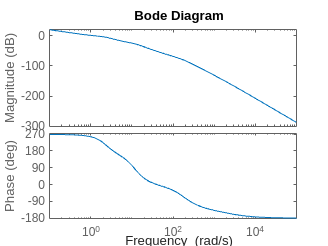

bode(G_xvref)

isstable(G_xvref)

ans = logical
   0


pole(G_xvref)

ans = 1.0e+03 *

   0.0000 + 0.0000i
  -1.6916 + 0.0000i
  -0.4371 + 0.0000i
  -0.1279 + 0.1222i
  -0.1279 - 0.1222i
  -0.0220 + 0.0000i
  -0.0068 + 0.0098i
  -0.0068 - 0.0098i
  -0.0073 + 0.0000i
  -0.0035 + 0.0000i




% Design parameters
gamma_m = 70+360%gamma_xvref;

gamma_m = 430

alpha = 0.9%alpha_xvref;

alpha = 0.9000


phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_m - 180;
[mag,phase,wout] = bode(G_xvref);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));

C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.7768 s + 1
  ------------
  0.6991 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_D*G_xvref),omega_c);
Kp = 1/mag;

G_xvref_ol = minreal(Kp*C_D*G_xvref)

G_xvref_ol =
 
                      -4.701e05 s^10 - 5.868e08 s^9 - 1.215e11 s^8 - 4.868e12 s^7 - 5.42e13 s^6 + 1.507e12 s^5 + 3.59e15 s^4 + 2.435e16 s^3 + 6.957e16 s^2 + 9.148e16 s + 4.479e16
  ----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^14 + 2438 s^13 + 1.445e06 s^12 + 3.295e08 s^11 + 3.855e10 s^10 + 1.579e12 s^9 + 3.254e13 s^8 + 4.101e14 s^7 + 3.212e15 s^6 + 1.546e16 s^5 + 4.63e16 s^4 + 8.641e16 s^3 + 9.382e16 s^2 + 4.427e16 s
 
Continuous-time transfer function.


G_xvref_cl = minreal(G_xvref_ol/(1+G_xvref_ol))

G_xvref_cl =
 
                          -4.701e05 s^14 - 1.388e09 s^13 - 1.133e12 s^12 - 2.261e14 s^11 - 1.129e16 s^10 - 2.198e17 s^9 - 1.781e18 s^8 + 6.909e16 s^7 + 1.192e20 s^6 + 1.055e21 s^5 + 4.737e21 s^4 + 1.254e22 s^3 + 1.97e22 s^2 + 1.691e22 s + 6.075e21
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^18 + 4144 s^17 + 5.627e06 s^16 + 2.851e09 s^15 + 6.348e11 s^14 + 7.525e13 s^13 + 3.669e15 s^12 + 9.691e16 s^11 + 1.624e18 s^10 + 1.845e19 s^9 + 1.462e20 s^8 + 8.232e20 s^7 + 3.352e21 s^6 + 1.001e22 s^5 + 2.2e22 s^4 + 3.475e22 s^3 + 3.688e22 s^2 + 2.292e22 s + 6.075e21
 
Continuous-time transfer function.


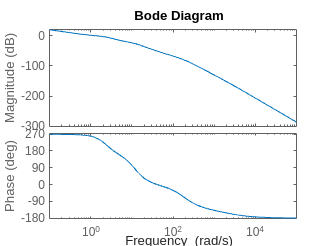


bode(G_xvref_ol)

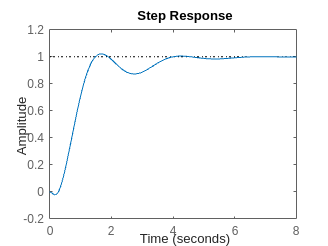

step(G_xvref_cl)

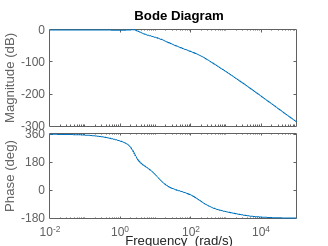

bode(G_xvref_cl)

[mag,phase,wout] = bode(G_xvref_cl)

mag = mag(:,:,1) =

    1.0000


mag(:,:,2) =

    0.9999


mag(:,:,3) =

    0.9999


mag(:,:,4) =

    0.9998


mag(:,:,5) =

    0.9997


mag(:,:,6) =

    0.9996


mag(:,:,7) =

    0.9995


mag(:,:,8) =

    0.9993


mag(:,:,9) =

    0.9990


mag(:,:,10) =

    0.9987


mag(:,:,11) =

    0.9982


mag(:,:,12) =

    0.9976


mag(:,:,13) =

    0.9967


mag(:,:,14) =

    0.9959


mag(:,:,15) =

    0.9956


mag(:,:,16) =

    0.9940


mag(:,:,17) =

    0.9919


mag(:,:,18) =

    0.9891


mag(:,:,19) =

    0.9853


mag(:,:,20) =

    0.9804


mag(:,:,21) =

    0.9740


mag(:,:,22) =

    0.9657


mag(:,:,23) =

    0.9553


mag(:,:,24) =

    0.9426


mag(:,:,25) =

    0.9275


mag(:,:,26) =

    0.9105


mag(:,:,27) =

    0.8925


mag(:,:,28) =

    0.8752


mag(:,:,29) =

    0.8613


mag(:,:,30) =

    0.8558


mag(:,:,31) =

    0.8543


mag(:,:,32) =

    0.8594


mag(:,:,33) =

    0.8747


mag(:,:,34) =

    0.9025


mag(:,:,35) =

    0.9391


mag(:,:,36) =

    0.97

phase = phase(:,:,1) =

  359.4337


phase(:,:,2) =

  359.0764


phase(:,:,3) =

  358.9220


phase(:,:,4) =

  358.7418


phase(:,:,5) =

  358.5316


phase(:,:,6) =

  358.2862


phase(:,:,7) =

  358.0000


phase(:,:,8) =

  357.6661


phase(:,:,9) =

  357.2767


phase(:,:,10) =

  356.8226


phase(:,:,11) =

  356.2934


phase(:,:,12) =

  355.6769


phase(:,:,13) =

  354.9593


phase(:,:,14) =

  354.3644


phase(:,:,15) =

  354.1247


phase(:,:,16) =

  353.1553


phase(:,:,17) =

  352.0313


phase(:,:,18) =

  350.7310


phase(:,:,19) =

  349.2313


phase(:,:,20) =

  347.5086


phase(:,:,21) =

  345.5397


phase(:,:,22) =

  343.3043


phase(:,:,23) =

  340.7866


phase(:,:,24) =

  337.9776


phase(:,:,25) =

  334.8767


phase(:,:,26) =

  331.4893


phase(:,:,27) =

  327.8195


phase(:,:,28) =

  323.8544


phase(:,:,29) =

  319.5350


phase(:,:,30) =

  316.6156


phase(:,:,31) =

  314.7086


phase(:,:,32) =

  309.0485


phase(:,:,33) =

  303.9889


phase(:,:,3

wout = 1.0e+05 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


[gpeak,fpeak] = findpeaks(squeeze(mag))

gpeak = 1.0452

fpeak = 39

fpeak=wout(fpeak(end))

fpeak = 2.2907

gpeak=gpeak(end)

gpeak = 1.0452

syms x0
tau_pre = double(vpasolve(abs(1/(x0*1i*fpeak+1)) == 1/gpeak));
G_pre = 1/(s*tau_pre+1)

G_pre =
 
       1
  ------------
  0.1328 s + 1
 
Continuous-time transfer function.
Model Properties


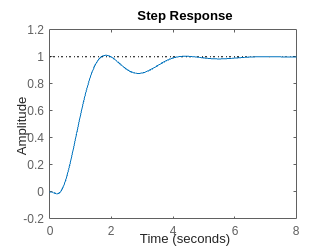

step(G_xvref_cl*G_pre)

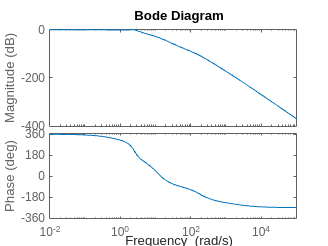

bode(G_xvref_cl*G_pre)

## Flush values to Simulink

[num_lead_xvref,den_lead_xvref] = tfdata(C_D,'v')

num_lead_xvref =     0.7768    1.0000


den_lead_xvref =     0.6991    1.0000


K_xvref = Kp

K_xvref = 1.0117

tau_pre_xvref = 0%tau_pre

tau_pre_xvref = 0

## X step test

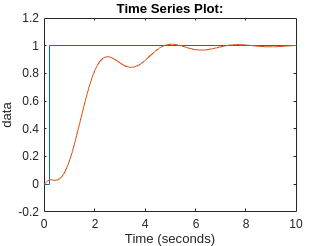

x_test = 1;
x_size = 1;

regsim = sim(model,10);

figure(1);
plot(regsim.ref);
hold on;
plot(regsim.x_pos);
hold off;

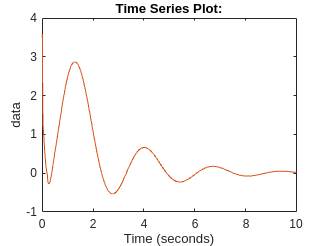


figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## v step size

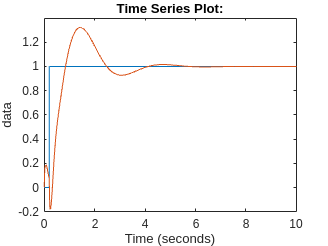

x_test = 0;
v_size = 1;

regsim = sim(model,10);

figure(1);
plot(regsim.vref);
hold on;
plot(regsim.vel);
hold off;

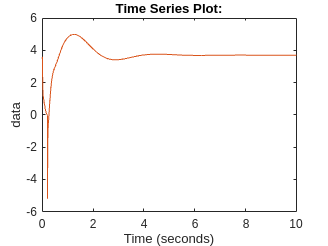


figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;

## Print controller values

K_vu

K_vu = 10.1357

t_i_vu

t_i_vu = 0.2727

K_post

K_post = -1

t_i_post

t_i_post = 0.1325

t_lead_tv

t_lead_tv = 0.0908

t_i_tv

t_i_tv = 0.0363

K_tv

K_tv = 1.9656

t_i_vreft

t_i_vreft = 2.3644

num_lead_vreft

num_lead_vreft =     0.6231    1.0000


den_lead_vreft

den_lead_vreft =     0.5608    1.0000


K_vreft

K_vreft = 0.2558

K_xvref

K_xvref = 0.9677

num_lead_xvref

num_lead_xvref =     0.6330    1.0000


den_lead_xvref

den_lead_xvref =     0.5697    1.0000


tau_pre_xvref

tau_pre_xvref = 0.4633